Ewell lab, 2025 gt.

Pipeline to reproduce Figure 4-5 and Extended Data Fig. 3. Some preprocessing step is needed between figure 3 and 4.

1) Input must be created for the FieldClusterApp using the main_CreateInput_Get_SI.m script (PlaceMaps.mat) in the folder *Discrimination 2025 CodeBase\Spatial remapping GT\SpatialRemapping*

2) The GUI is used to extract individual place field and calculate the rate and size properties of each field. The GUI outputs the FieldClustering.mat structure for each session.

3) Next, a table (FieldTbl.mat) is created with all the important properties of each individual field, and fields classified as reward-fields/non-reward fields. For details see MakeFieldTable.m. 

4) Rate remapping analysis relies on 3 files for each session: FieldClustering.mat, PlaceMaps.mat, FieldTbl.mat.

5) Mismatch analysis can be found in the *Mismatch analysis* subfolder and uses a separate MisMatchTbl.mat file that is created with MakeMismatchTable.m script.

main_path = "C:\Users\ewell\Desktop\TestCodeGitHub\";
main_path

main_path = "G:\"

warning('off') %turn off warnings
addpath(strcat(main_path, "Discrimination 2025 CodeBase\Rate remapping\"))
addpath(strcat(main_path, "Discrimination 2025 CodeBase\Rate remapping\Mismatch analysis\"))

First load files for the rate overlap analysis and extract rate overlap for place fields.

% all discrimination session
workdir_d = [strcat(main_path, "\CA1 miniscope data\M119\TrainingD11\")  strcat(main_path,"\CA1 miniscope data\M120\TrainingD11\")  strcat(main_path,"\CA1 miniscope data\M292\TrainingD6\")  strcat(main_path,"\CA1 miniscope data\M319\TrainingD7\") strcat(main_path,"\CA1 miniscope data\M231\TrainingD9\") strcat(main_path,"\CA1 miniscope data\M314\Training_Separation_D5\") strcat(main_path,"\CA1 miniscope data\M316\Training_Separation_D6\")  strcat(main_path,"\CA1 miniscope data\M318\Training_Separation_D4\") strcat(main_path,"\CA1 miniscope data\M210\TrainingD17\")];
% all generalization session
workdir_g = [strcat(main_path, "\CA1 miniscope data\M119\GroupingD6\") strcat(main_path, "\CA1 miniscope data\M120\GroupingD6\") strcat(main_path, "\CA1 miniscope data\M292\GroupingD3\") strcat(main_path, "\CA1 miniscope data\M319\GroupingD4\") strcat(main_path, "\CA1 miniscope data\M231\GroupingD5\") strcat(main_path, "\CA1 miniscope data\M314\GroupingD3\") strcat(main_path, "\CA1 miniscope data\M316\GroupingD3\") strcat(main_path, "\CA1 miniscope data\M318\GroupingD3\") ];
discrimination = [1 1 1 1 2 2 2 2 1];
grouping = [2 2 2 2 1 1 1 1 0];
OverlappingWall = [2 2 1 1 2 1 2 1 1];
Sex = ["f" "f" "f" "m" "f" "m" "m" "m"];
colors = ["#46bb91" "#93EB74" "#BCEAC5" "#9576b4" "#875FEA" "#D093EB" ];
[All_d, Cohort_d, Individual_d] = WrapRateOverlap(workdir_d, discrimination);

G:\\CA1 miniscope data\M119\TrainingD11\
G:\\CA1 miniscope data\M120\TrainingD11\
G:\\CA1 miniscope data\M292\TrainingD6\
G:\\CA1 miniscope data\M319\TrainingD7\
G:\\CA1 miniscope data\M231\TrainingD9\
G:\\CA1 miniscope data\M314\Training_Separation_D5\
G:\\CA1 miniscope data\M316\Training_Separation_D6\
G:\\CA1 miniscope data\M318\Training_Separation_D4\
G:\\CA1 miniscope data\M210\TrainingD17\


[All_g, Cohort_g, Individual_g] = WrapRateOverlap(workdir_g, discrimination);

G:\\CA1 miniscope data\M119\GroupingD6\
G:\\CA1 miniscope data\M120\GroupingD6\
G:\\CA1 miniscope data\M292\GroupingD3\
G:\\CA1 miniscope data\M319\GroupingD4\
G:\\CA1 miniscope data\M231\GroupingD5\
G:\\CA1 miniscope data\M314\GroupingD3\
G:\\CA1 miniscope data\M316\GroupingD3\
G:\\CA1 miniscope data\M318\GroupingD3\


## Figure 4b

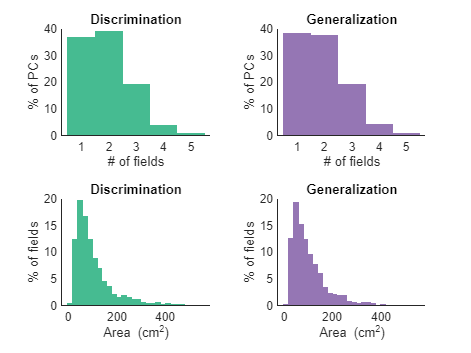

figure
tiledlayout(2,2)
nexttile;
histogram(All_d.NFields, "Normalization","percentage", "FaceColor",colors(1), "EdgeColor", colors(1),FaceAlpha=1)
box off
xlabel("# of fields")
ylabel("% of PCs")
title("Discrimination")

nexttile;
histogram(All_g.NFields, "Normalization","percentage", "FaceColor",colors(4), "EdgeColor", colors(4), FaceAlpha=1)
box off
xlabel("# of fields")
ylabel("% of PCs")
title("Generalization")

nexttile;
histogram(All_d.Size*2, "Normalization","percentage", "FaceColor",colors(1), "EdgeColor", colors(1), FaceAlpha=1)
box off
xlabel("Area (cm{^2})")
ylabel("% of fields")
title("Discrimination")

nexttile;
histogram(All_g.Size*2, "Normalization","percentage", "FaceColor",colors(4), "EdgeColor", colors(4), FaceAlpha=1)
box off
xlabel("Area (cm{^2})")
ylabel("% of fields")
title("Generalization")

## Figure 4d-e

p = 0.5437

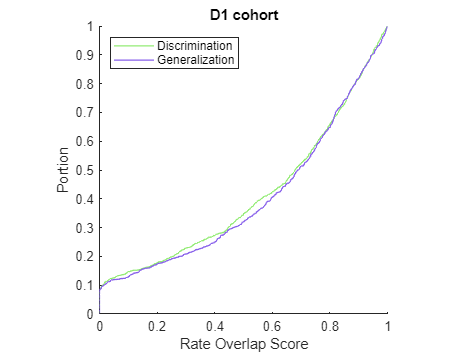

p = 0.0608

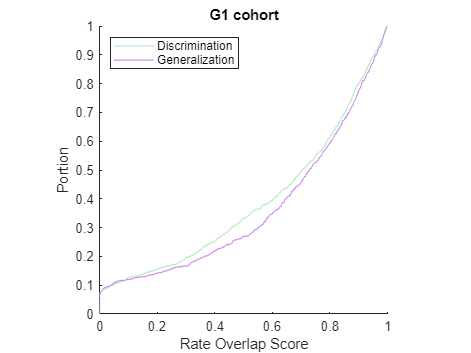

for i =1:2
    [ydCoh{i}, xdCoh{i}] = ecdf(Cohort_d.ROS{i});
    [ygCoh{i}, xgCoh{i}] = ecdf(Cohort_g.ROS{i});
end

titles = ["D1 cohort", "G1 cohort"];

for i = 1:2
    p = ranksum(Cohort_d.ROS{i},Cohort_g.ROS{i})
    figure
    plot(xdCoh{i}, ydCoh{i}, LineWidth=1, Color=colors(1+i))
    hold on
    plot(xgCoh{i}, ygCoh{i}, LineWidth=1, Color=colors(4+i))
    box off
    xlabel("Rate Overlap Score")
    ylabel("Portion")
    title(titles(i))
    axis square
    legend("Discrimination", "Generalization", "Location","northwest")
end

## Figure 4f-g

figure
p = ranksum(Cohort_d.ROS{1},Cohort_d.ROS{2})

p = 0.0572

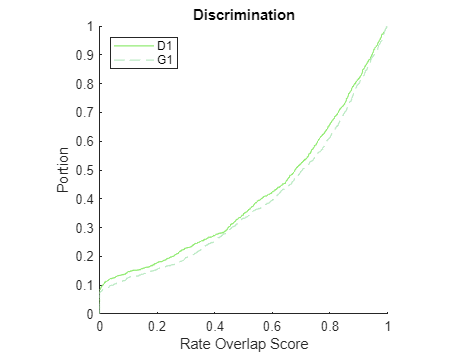

hold on
plot(xdCoh{1}, ydCoh{1}, LineWidth=1, Color=colors(2))
plot(xdCoh{2}, ydCoh{2}, LineWidth=1, Color=colors(3), LineStyle="--")
box off
xlabel("Rate Overlap Score")
ylabel("Portion")
title("Discrimination")
axis square
legend("D1", "G1", "Location","northwest")


figure
p = ranksum(Cohort_g.ROS{1},Cohort_g.ROS{2})

p = 0.0068

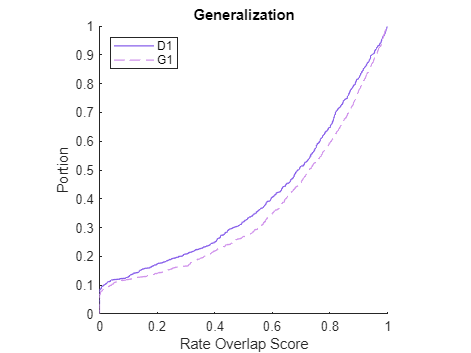

hold on
plot(xgCoh{1}, ygCoh{1}, LineWidth=1, Color=colors(5))
plot(xgCoh{2}, ygCoh{2}, LineWidth=1, Color=colors(6), LineStyle="--")
box off
xlabel("Rate Overlap Score")
ylabel("Portion")
title("Generalization")
axis square
legend("D1", "G1", "Location","northwest")

## Figure 5b

Note that on the figure the last 3 bins of generalization are pooled on the figure. Note that colors are different on the figure that code for the different distances.

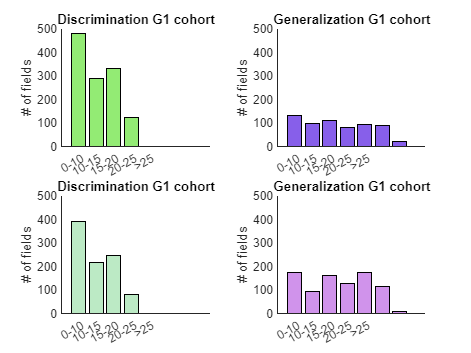

for j = 1:2
    [ROSdist_Cohd{j},n_Cohd{j}, edges_Cohd{j}] = GetROS_Dist(Cohort_d.RewDist{j}, Cohort_d.ROS{j});
    [ROSdist_Cohg{j},n_Cohg{j}, edges_Cohg{j}] = GetROS_Dist(Cohort_g.RewDist{j}, Cohort_d.ROS{j});
end
n_rewd = [480 391];
n_rewg = [135 175];

figure
tiledlayout(2,2)
for j =1:2
    nexttile;
    bar([n_rewd(j); n_Cohd{j}(3:end)], "FaceColor", colors(1+j))
    box off
    ylim([0 500])
    xlim([0 8.5])
    ylabel("# of fields")
    xticks(1:5)
    xticklabels({"0-10", "10-15", "15-20", "20-25", ">25"})
    title(strcat("Discrimination ", titles(i)))
    
    nexttile;
    bar([n_rewg(j); n_Cohg{j}(3:end)], "FaceColor", colors(4+j))
    box off
    ylim([0 500])
    xlim([0 8.5])
    ylabel("# of fields")
    xticks(1:5)
    xticklabels({"0-10", "10-15", "15-20", "20-25", ">25"})
    title(strcat("Generalization ", titles(i)))
end

## Figure 5 c-d

p = 0.0100

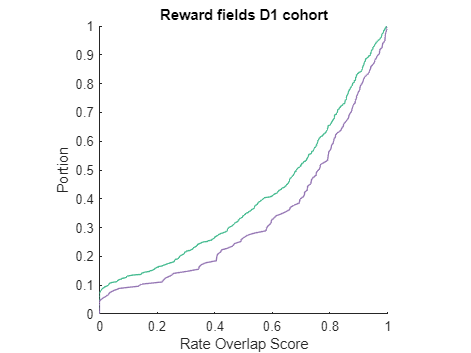

p = 0.0266

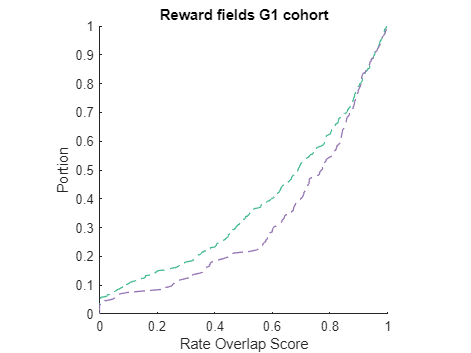

for i =1:2
    [ydRCoh{i}, xdRCoh{i}] = ecdf(Cohort_d.RewROS{i});
    [ygRCoh{i}, xgRCoh{i}] = ecdf(Cohort_g.RewROS{i});
end

style = ["-", "--"];
for i = 1:2
    p = ranksum(Cohort_d.RewROS{i}, Cohort_g.RewROS{i})
    figure
    hold on
    plot(xdRCoh{i}, ydRCoh{i}, LineWidth=1, Color=  colors(1), LineStyle =style(i))
    plot(xgRCoh{i}, ygRCoh{i}, LineWidth=1, Color= colors(4), LineStyle =style(i))
    box off
    axis square
    xlabel("Rate Overlap Score")
    ylabel("Portion")
    title(strcat("Reward fields ", titles(i)))
    
end

## Figure 5 f-g

## Extended Data Figure 3

Note that colors are different on the figure that code for the different distances. 1st row is D1 cohort panel a-c; 2nd row is G1 cohort panel a-c.

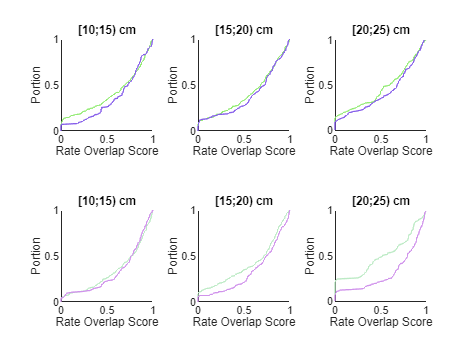

ans =     1.0000
    1.0000
    0.8551


ans =     1.0000
    0.0465
    0.0003


SortedFields_d = cell(2,1);
SortedFields_g = cell(2,1);
dist_pval = cell(2,1);
edges_d = edges_Cohd{1};
edges_g = edges_Cohg{1};
figure
tiledlayout(2,3)
for n = 1:2
SortedFields_d{n} = nan(350,8);
SortedFields_g{n} = nan(350,8);

for i = 3:length(edges_d)-1
    FieldsToUse = find(Cohort_d.RewDist{n} >= edges_d(i) & Cohort_d.RewDist{n} < edges_d(i+1));
    if ~isempty(FieldsToUse)
        SortedFields_d{n}(1:length(FieldsToUse),i) = Cohort_d.ROS{n}(FieldsToUse);
    end
end

for i = 3:length(edges_g)-1
    FieldsToUse = find(Cohort_g.RewDist{n} >= edges_g(i) & Cohort_g.RewDist{n} < edges_g(i+1));
    if ~isempty(FieldsToUse)
        SortedFields_g{n}(1:length(FieldsToUse),i) = Cohort_g.ROS{n}(FieldsToUse);
    end
end

dist_pval{n} = zeros(3,1);


for i = 3:5
    
    [yd,xd] = ecdf(SortedFields_d{n}(:,i));
    [yg,xg] = ecdf(SortedFields_g{n}(:,i));
    dist_pval{n}(i-2) = ranksum(SortedFields_d{n}(:,i), SortedFields_g{n}(:,i));
    nexttile;
    plot(xd,yd,"Color", colors(1+n))
    hold on
    plot(xg,yg,"Color", colors(4+n))
    box off
    axis square
    title(strcat("[", num2str((i-1)*5), ";", num2str(i*5), ") cm"))
    xlabel("Rate Overlap Score")
    ylabel("Portion")

end
dist_pval{n} = dist_pval{n}.*3; % stats with Bonferroni
dist_pval{n}(dist_pval{n} > 1) = 1;
dist_pval{n}
end

## Figure 5e

Mismatch analysis - uses a different file (MisMatchTbl.mat). Only the correct testing trials are included in this analysis and only for the discrimination.

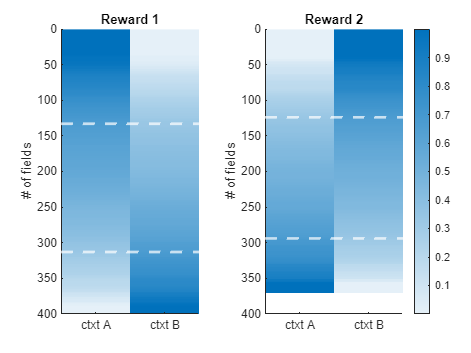

[FiringPref, RZ_ID, MeanRate] = WrapMisMatch(workdir_d);
rate_ordered = GetMisMatchMatrix(MeanRate,RZ_ID, FiringPref); % get ordered event rate

figure
tiledlayout(1,2)
for i = 1:2
nexttile;
imagesc(rate_ordered{i})
hold on
[~, idx] = min(abs(rate_ordered{i}(:,i)-0.666));

yline(idx, "w--", LineWidth=2)
[~, idx] = min(abs(rate_ordered{i}(:,i)-0.333));
yline(idx, "w--", LineWidth=2)
box off
colormap sky
xticks([1 2])
xticklabels({"ctxt A", "ctxt B"})
ylabel('# of fields')
ylim([0 400])
title(strcat("Reward ", num2str(i)))
end
colorbar